# FMCW Radar Lab: Target Tracking

This lab combines a number of concepts to demonstrate a tracking radar. In this script, we beamform to multiple directions and perform the CFAR algorithm to generate detections with estimates of range, speed, and direction of arrival. We then use this information to generate tracks to follow targets in the field of view.

## System Setup

Before going through the lab, we prepare the workspace by clearing variables, closing figures, suppressing warnings.

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin');

For this lab, we use many of the same parameters that were used in previous labs.

% Setup Phaser
fc = 10e9;
prf = 1000;
nPulses = 48;
fs = 1e6;
rampbandwidth = 500e6;
[rx,tx,bf,bf_TDD] = setupLabRadar(fc,prf,nPulses,fs,rampbandwidth);

% Setup MTI
mti = [1 -2 1];
%nfilt = length(mti);
nfilt = 0;

% Setup the array model for steering
lambda = freq2wavelen(10.7e9);
spacing = lambda/2;
array = phased.ULA(NumElements=8,ElementSpacing=spacing);
elementPosition = array.getElementPosition();

Load the calibration weights which are required for steering the antenna.

load('CalibrationWeights.mat','calibrationweights');

## Signal Processing Setup

Setup the range-Doppler processing object.

tSweep = double(bf.FrequencyDeviationTime)/1e6;
sweepSlope = rampbandwidth/tSweep;
rd = phased.RangeDopplerResponse(DopplerOutput="Speed",...
    OperatingFrequency=fc,SampleRate=fs,RangeMethod="FFT",...
    SweepSlope=sweepSlope,PRFSource="Property",PRF=prf);

Setup the CFAR detector.

pfa = 1e-6;
guard = 2;
train = 2;
cfar = phased.CFARDetector2D(ProbabilityFalseAlarm=pfa,GuardBandSize=[guard guard],TrainingBandSize=[train train],NoisePowerOutputPort=true);

We look for moving targets out to 30 meters.

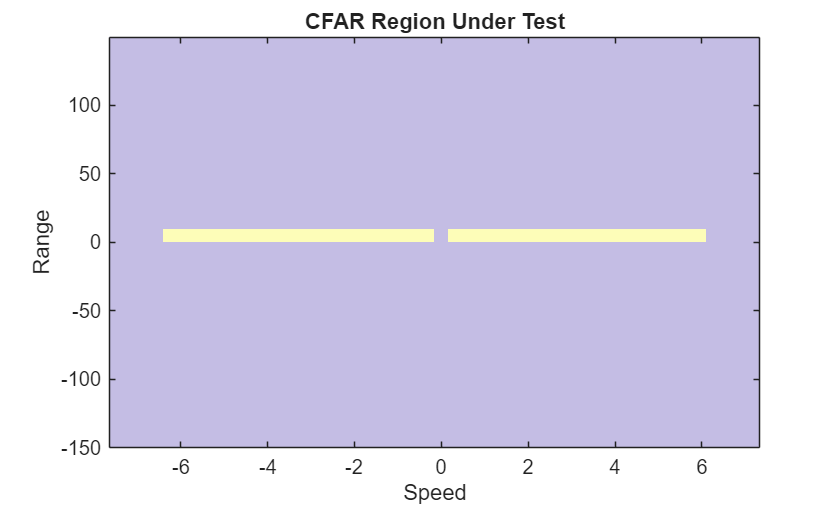

minRange = 0.1;
maxRange = 10;
vmin = 0.25;
vmax = inf;
[cut,speed,range] = getCFARCUT(minRange,maxRange,vmin,vmax,guard,train,prf,nPulses,fc,fs,tSweep,rampbandwidth);
plotCFARRegion(cut,range,speed);

The yellow regions are the regions of the range-Doppler space that we will be testing for detections.

We setup some properties for detection definition. The measurement parameters define the coordinates. The measurement noise is derived from the expected azimuth error, the range resolution, and the velocity resolution.

detParams = struct(Frame="spherical",HasElevation=false);
azErr = 30;
rangeErr = range(2)-range(1);
speedErr = speed(2)-speed(1);
measNoise = diag([azErr;rangeErr;speedErr]);

A JPDA tracker with a motion model based on human walking is used.

trackGenerator = TrackGenerator();

## Data Collection

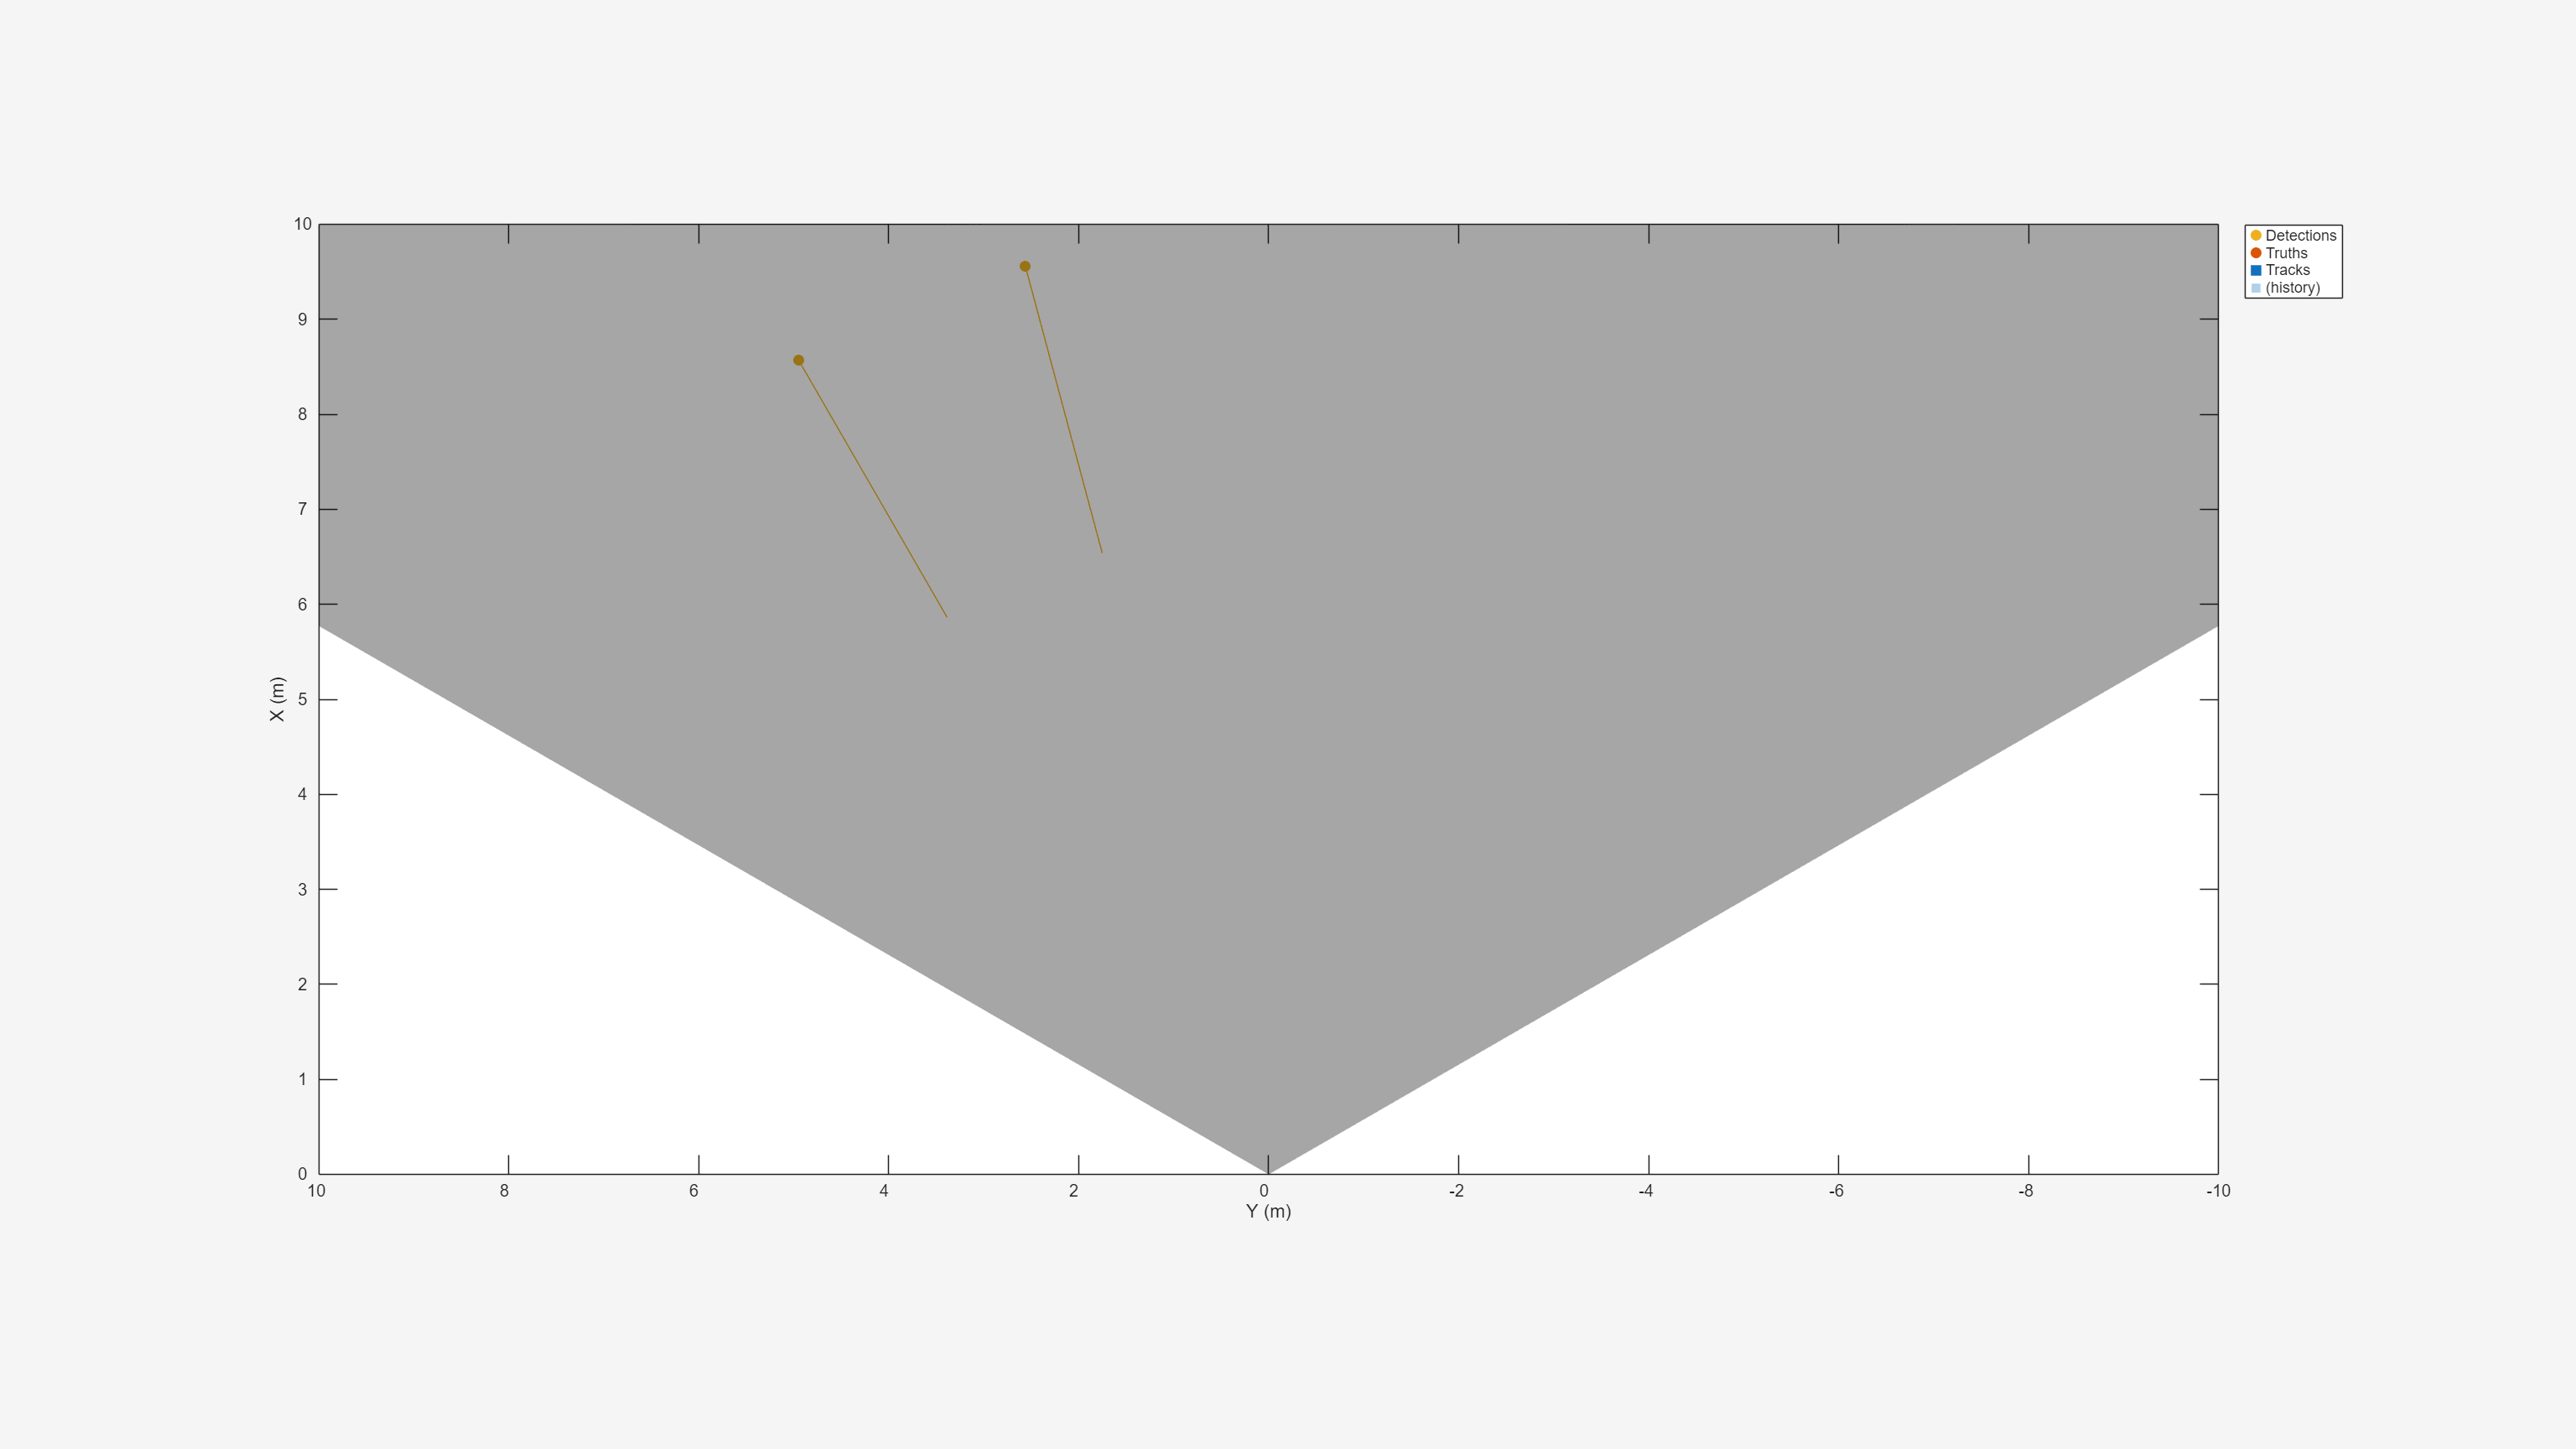

% Run time in seconds
tCapture = 60;

% Setup the steering angles
steerang = -45:15:45;
nang = length(steerang);

% Create a display object
display = HelperRadarTrackingDisplay('XLimits',[0 maxRange],...
    'YLimits',[-maxRange maxRange],...
    'MaxRange',30,...
    'CameraReferenceLines',zeros(2,0),...
    'RadarReferenceLines',zeros(2,0),...
    'PlotReferenceImage',0);
display(objectDetection.empty(0,1),objectTrack.empty(0,1),[]);
% Initialize the data capture
captureTransmitWaveform(rx,tx,bf);

% Save the number of range and Doppler cells
nrange = length(range);
nspeed = length(speed);

tseed = tic;
t = toc(tseed);
while t < tCapture
    % Update time
    t = toc(tseed);

    % First, capture data steering across the field of view.
    data = cell(1,nang);
    for iang = 1:nang
        % Steer the analog beamformers
        cang = steerang(iang);
        steerweights = steervec(elementPosition,[cang;0]);
        analogsteer = analogWeightsCalAdjustment([steerweights(1:4) steerweights(5:8)],calibrationweights.AnalogWeights);
        setAnalogBfWeights(bf,analogsteer);

        % Trigger burst pulse
        bf.Burst=false;bf.Burst=true;bf.Burst=false;

        % Capture pulse period
        data{iang} = rx();
    end

    % Perform CFAR on each set of data after MTI filtering
    rdprocessed = zeros(nrange,nspeed,nang);
    detblock = 1000;
    detectionMeasurements = zeros(4,detblock);
    startDetIdx = 1;
    for iang = 1:nang
        % Save the steer angle
        cang = steerang(iang);

        % Arrange data into pulses
        datapulse = arrangePulseData(data{iang},rx,bf,bf_TDD);

        % Apply MTI filter, remove pulses in transient region
        %datafilter = filter(mti,1,datapulse,[],2);
        %datafilter = datafilter(:,nfilt:end);
        datafilter = datapulse;

        % Perform range-Doppler processing
        [rddata,range,speed] = rd(datafilter);

        % Get index of detections
        [d,noise] = cfar(abs(rddata).^2,cut);
        detidx = cut(:,d');

        % Get the range, speed, steer angle, and SNR for the detections
        detRange = range(detidx(1,:))';
        detSpeed = speed(detidx(2,:))';
        detSteer = repmat(cang,1,length(detRange));
        detnoise = noise(d).';
        detpow = abs(arrayfun(@(row,col)rddata(row,col),detidx(1,:),detidx(2,:))).^2;
        detsnr = detpow./detnoise;

        % Save detections and RD response for angle processing
        ndets = size(detidx,2);
        endDetIdx = startDetIdx + ndets - 1;

        % Handle overflow if we exceed pre-allocated number of detections
        if endDetIdx > size(detectionMeasurements,2)
            newdetections = zeros(4,endDetIdx);
            newdetections(:,1:startDetIdx-1) = detectionMeasurements;
            detectionMeasurements = newdetections;
        end

        % Save detection values
        detectionMeasurements(:,startDetIdx:endDetIdx) = [detRange;detSpeed;detSteer;detsnr];
        startDetIdx = endDetIdx + 1;
        rdprocessed(:,:,iang) = rddata;
    end

    % Get only the populated detection values
    if startDetIdx == 1
        continue
    else
        detectionMeasurements = detectionMeasurements(:,1:startDetIdx-1);
    end

    % Get cluster detections in range-Doppler
    detClusters = dbscan(detectionMeasurements(1:2,:).',1,3);

    % Create an objectDetection for each cluster
    singles = detClusters == -1;
    nSingles = sum(singles);
    clusters = unique(detClusters(detClusters > 0));
    nClusters = length(clusters);
    nDetections = nSingles + nClusters;
    detections = cell(nDetections,1);
    didx = 1;

    % Create detections from the unclustered measurements
    unclustered = detectionMeasurements(1:3,singles);
    for isingle = 1:nSingles
        az = unclustered(3,isingle);
        range = unclustered(1,isingle);
        speed = unclustered(2,isingle);
        measurement = [az;range;speed];
        detections{didx} = objectDetection(t,measurement,MeasurementNoise=measNoise,MeasurementParameters=detParams);
        didx = didx + 1;
    end

    % Create detections from the clustered measurements
    for icluster = 1:nClusters
        % Get values for current cluster
        clusterValues = detectionMeasurements(:,detClusters == icluster);

        % Range and speed are the means
        clusterRange = mean(clusterValues(1,:));
        clusterSpeed = mean(clusterValues(2,:));

        % AOA is the max SNR value
        [~, aoaIdx] = max(clusterValues(4,:));
        clusterAz = clusterValues(3,aoaIdx);

        % Save the measurements
        measurement = [clusterAz;clusterRange;clusterSpeed];
        detections{didx} = objectDetection(t,measurement,MeasurementNoise=measNoise,MeasurementParameters=detParams);
        didx = didx + 1;
    end
    
    % Create tracks from detections
    tracks = trackGenerator.track(detections,t);

    % Display results
    display(detections,tracks,[]);
end


% Disable TDD Trigger
cleanupAntenna(rx,tx,bf,bf_TDD);

function ax = plotCFARRegion(cut,range,speed)
    % Plot the CFAR region that will be tested for detections
    
    % Create axes to plot region
    ax = axes(figure);
    
    % Plot the cfar region image
    cfartest = zeros(length(range),length(speed));
    ncut = size(cut,2);
    for iCut = 1:ncut
        cfartest(cut(1,iCut),cut(2,iCut)) = 1;
    end
    imagesc(ax,speed,range,cfartest,'AlphaData',0.3);
    
    % Update axes
    title(ax,'CFAR Region Under Test');
    xlabel(ax,'Speed');
    ylabel(ax,'Range');
    ax.YDir = "Normal";
end